# Robotics Midterm Test - 2019-04-29

## Exercise 2: PRP Robot

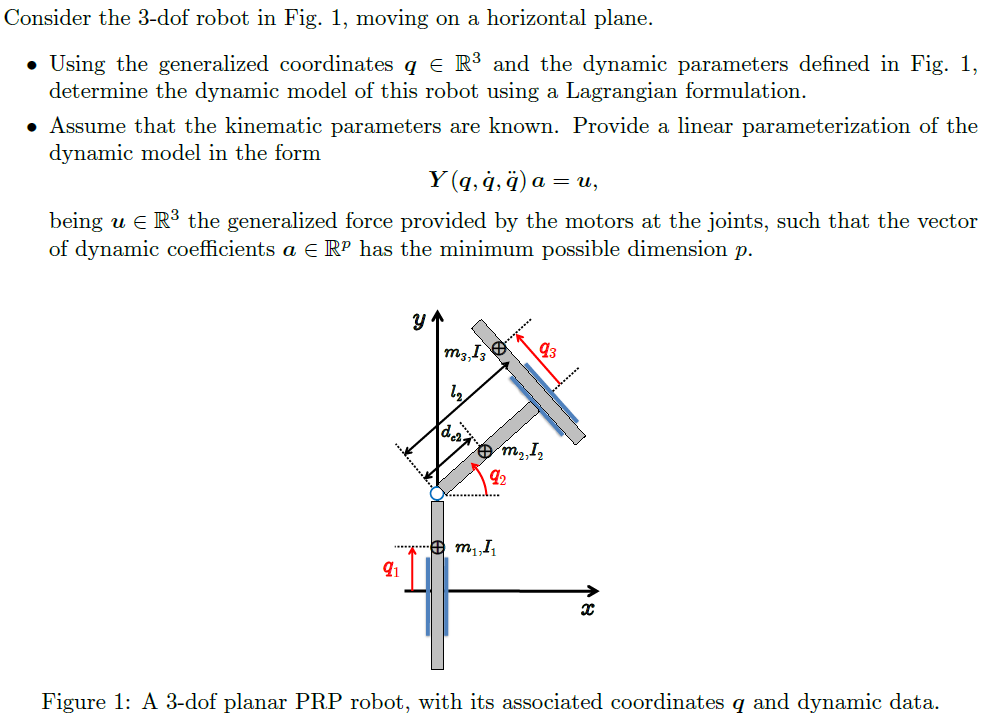

### Automatic attempt

clear;clc
sigma = [1,0,1];
n = length(sigma);
q = sym('q', [1 n]);
qd = sym('qd', [1 n]);
qdd = sym('qdd', [1 n]); 
d = sym('d', [1 n]);
a = sym('a', [1 n]);
l = sym('l', [1 n]);
m = sym('m', [1 n]);
I = sym('I', [1 n]);

%       alpha   a   d   theta
dhTable = [pi/2  0    q(1)    0;
           -pi/2  l(2) 0       q(2);
           0      0   q(3)    0]

$$dhTable = \left(\begin{array}{cccc} \frac{\pi }{2} & 0 & q_{1} & 0\\ -\frac{\pi }{2} & l_{2} & 0 & q_{2}\\ 0 & 0 & q_{3} & 0 \end{array}\right)$$



% L(n)=LINK([theta D A alpha Sigma(optional) Offset(optional)])
% Must only specify either THETA or D

% L(1) = Link('a', 0, 'alpha', pi/2,  'theta', 0,'qlim',[0,10]); % Prismatic
% L(2) = Link('a', 10, 'alpha', -pi/2, 'd', 0,'qlim',[0,pi]); % Revolute
% L(3) = Link('a', 0, 'alpha', 0,     'theta', 0,'qlim',[0,10]); % Prismatic
% prpRobot = SerialLink(L, 'name', 'PRP_Robot ')
% prpRobot.teach
% % 
rc = [0,0,q(1);
    d(2),0,0;
   0,0,q(3)].'

$$rc = \left(\begin{array}{ccc} 0 & d_{2} & 0\\ 0 & 0 & 0\\ q_{1} & 0 & q_{3} \end{array}\right)$$

I = sym(zeros(3,3,n));
%rc = []
for i = 1:n
 %   rc = [rc [-l(i)+d(i); 0; 0]];
    I(:,:,i) = diag(sym(strcat({'Ixx','Iyy','Izz'},int2str(i))));
end
      

M = getM(dhTable, sigma, qd, rc,m,I)

----------------------------- LINK 1 -----------------------------------
T_i
      2
m1 qd1
-------
   2

----------------------------- end ------------------------------------
----------------------------- LINK 2 -----------------------------------
T_i
       2        2                                  2            2
m2 (qd1  sin(q2)  + (d2 qd2 + l2 qd2 + qd1 cos(q2)) )   Iyy2 qd2
----------------------------------------------------- + ---------
                          2                                 2

----------------------------- end ------------------------------------
----------------------------- LINK 3 -------------

$$M = \left(\begin{array}{ccc} m_{1}+m_{2}+m_{3} & d_{2}\,m_{2}\,\cos\left(q_{2}\right)+l_{2}\,m_{2}\,\cos\left(q_{2}\right)+l_{2}\,m_{3}\,\cos\left(q_{2}\right)-2\,m_{3}\,q_{3}\,\sin\left(q_{2}\right) & m_{3}\,\cos\left(q_{2}\right)\\ \frac{m_{3}\,\left(2\,l_{2}\,\cos\left(q_{2}\right)-4\,q_{3}\,\sin\left(q_{2}\right)\right)}{2}+m_{2}\,\cos\left(q_{2}\right)\,\left(d_{2}+l_{2}\right) & {\mathrm{Iyy}}_{2}+{\mathrm{Iyy}}_{3}+m_{2}\,{\left(d_{2}+l_{2}\right)}^{2}+\frac{m_{3}\,\left(2\,{l_{2}}^{2}+8\,{q_{3}}^{2}\right)}{2} & l_{2}\,m_{3}\\ m_{3}\,\cos\left(q_{2}\right) & l_{2}\,m_{3} & m_{3} \end{array}\right)$$

%% Cannot get the proper result


### Manual Attempt

% This part is isolated from previous section
clear;clc

syms k q1(t) q2(t) q3(t)
sigma = [1,0,1];
n = length(sigma);
q = sym('q', [1 n]);
qd = sym('qd', [1 n]);
qdd = sym('qdd', [1 n]); 

d = sym('d', [1 n]);
l = sym('l', [1 n]);
m = sym('m', [1 n]);
I = sym('I', [1 n]);


%Insert manually the global positions of the centers of mass
pc(:,1) = [0 q1];
pc(:,2) = [d(2)*cos(q2), q1+k+d(2)*sin(q2)];
pc(:,3) = [l(2)*cos(q2)-q3*sin(q2), q1+k+l(2)*sin(q2)+q3*cos(q2)]

$$pc = \left(\begin{array}{ccc} 0 & d_{2}\,\cos\left(q_{2}\left(t\right)\right) & l_{2}\,\cos\left(q_{2}\left(t\right)\right)-\sin\left(q_{2}\left(t\right)\right)\,q_{3}\left(t\right)\\ q_{1}\left(t\right) & k+q_{1}\left(t\right)+d_{2}\,\sin\left(q_{2}\left(t\right)\right) & k+q_{1}\left(t\right)+l_{2}\,\sin\left(q_{2}\left(t\right)\right)+\cos\left(q_{2}\left(t\right)\right)\,q_{3}\left(t\right) \end{array}\right)$$

vc = diff(pc,t)

$$vc = \left(\begin{array}{ccc} 0 & -d_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right) & -\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{3}\left(t\right)-\cos\left(q_{2}\left(t\right)\right)\,q_{3}\left(t\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)-l_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\\ \frac{\partial }{\partial t}q_{1}\left(t\right) & \frac{\partial }{\partial t}q_{1}\left(t\right)+d_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right) & \cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{3}\left(t\right)+\frac{\partial }{\partial t}q_{1}\left(t\right)-\sin\left(q_{2}\left(t\right)\right)\,q_{3}\left(t\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)+l_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right) \end{array}\right)$$

% Substitute the literals just for visualization, as we don't need to
% derivate
vc=subs(vc, [diff(q1(t), t), diff(q2(t), t), diff(q3(t), t)], qd);

vc=subs(vc, [q1,q2,q3], q);
w =[0, qd(2), qd(2)].';
for i=1:n
 T(i) = (1/2)*m(i)*(vc(:,i).'*vc(:,i)) + (1/2)*w(i)*I(i)*w(i);
end
KE = sum(T.')

$$KE = \frac{I_{2}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{I_{3}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{2}\,\left({\left({\mathrm{qd}}_{1}+d_{2}\,{\mathrm{qd}}_{2}\,\cos\left(q_{2}\right)\right)}^{2}+{d_{2}}^{2}\,{{\mathrm{qd}}_{2}}^{2}\,{\sin\left(q_{2}\right)}^{2}\right)}{2}+\frac{m_{1}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{3}\,\left({\left({\mathrm{qd}}_{1}+{\mathrm{qd}}_{3}\,\cos\left(q_{2}\right)+l_{2}\,{\mathrm{qd}}_{2}\,\cos\left(q_{2}\right)-q_{3}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right)\right)}^{2}+{\left({\mathrm{qd}}_{3}\,\sin\left(q_{2}\right)+q_{3}\,{\mathrm{qd}}_{2}\,\cos\left(q_{2}\right)+l_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right)\right)}^{2}\right)}{2}$$

% Get the coeficients of the terms. That builds the M matrix
M = getInertiaMatrixFromKE(KE,qd)

$$M = \begin{array}{l} \left(\begin{array}{ccc} m_{1}+m_{2}+m_{3} & \frac{m_{3}\,\left(2\,l_{2}\,\cos\left(q_{2}\right)-2\,q_{3}\,\sin\left(q_{2}\right)\right)}{2}+\sigma_{1} & m_{3}\,\cos\left(q_{2}\right)\\ \sigma_{1}+l_{2}\,m_{3}\,\cos\left(q_{2}\right)-m_{3}\,q_{3}\,\sin\left(q_{2}\right) & m_{2}\,{d_{2}}^{2}+m_{3}\,{l_{2}}^{2}+m_{3}\,{q_{3}}^{2}+I_{2}+I_{3} & l_{2}\,m_{3}\\ m_{3}\,\cos\left(q_{2}\right) & l_{2}\,m_{3} & m_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=d_{2}\,m_{2}\,\cos\left(q_{2}\right) \end{array}$$

### Dynamic parameters identification

From the final expression of the Robot dynamic model , it's possible to extract the dynamic parameters, agrouping constant terms.

% It might take a while
[Msubs, dynamicParameters, a] = getDynamicParameters(M,q,l)

>> Getting dynamic coefficients. Might take a while...


$$dynamicParamsReturn = \left(\begin{array}{c} m_{1}+m_{2}+m_{3}\\ m_{3}\\ d_{2}\,m_{2}\\ m_{2} \end{array}\right)$$

$$Msubs = \left(\begin{array}{ccc} a_{1} & a_{3}\,\cos\left(q_{2}\right)+a_{2}\,l_{2}\,\cos\left(q_{2}\right)+a_{4}\,l_{2}\,\cos\left(q_{2}\right)-2\,a_{2}\,q_{3}\,\sin\left(q_{2}\right) & a_{2}\,\cos\left(q_{2}\right)\\ \frac{a_{2}\,\left(2\,l_{2}\,\cos\left(q_{2}\right)-4\,q_{3}\,\sin\left(q_{2}\right)\right)}{2}+a_{4}\,\cos\left(q_{2}\right)\,\left(d_{2}+l_{2}\right) & {\mathrm{Iyy}}_{2}+{\mathrm{Iyy}}_{3}+a_{4}\,{\left(d_{2}+l_{2}\right)}^{2}+\frac{a_{2}\,\left(2\,{l_{2}}^{2}+8\,{q_{3}}^{2}\right)}{2} & a_{2}\,l_{2}\\ a_{2}\,\cos\left(q_{2}\right) & a_{2}\,l_{2} & a_{2} \end{array}\right)$$

$$dynamicParameters = \left(\begin{array}{c} m_{1}+m_{2}+m_{3}\\ m_{3}\\ d_{2}\,m_{2}\\ m_{2} \end{array}\right)$$

$$a = \left(\begin{array}{cccc} a_{1} & a_{2} & a_{3} & a_{4} \end{array}\right)$$

% Torque full expression
MCs = getcS(Msubs,q.', qd.')

$$MCs = \left(\begin{array}{c} \left(-{\mathrm{qd}}_{2}\,\left(\frac{3\,a_{2}\,{\mathrm{qd}}_{3}}{2}+{\mathrm{qd}}_{2}\,\left(a_{2}\,l_{2}+a_{4}\,\left(d_{2}+l_{2}\right)\right)\right)-\frac{3\,a_{2}\,{\mathrm{qd}}_{2}\,{\mathrm{qd}}_{3}}{2}\right)\,\sin\left(q_{2}\right)+\left(-2\,a_{2}\,q_{3}\,{{\mathrm{qd}}_{2}}^{2}\right)\,\cos\left(q_{2}\right)\\ \left(\frac{a_{4}\,d_{2}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}}{2}-\frac{a_{3}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}}{2}-a_{2}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{3}\right)\,\sin\left(q_{2}\right)+8\,a_{2}\,q_{3}\,{\mathrm{qd}}_{2}\,{\mathrm{qd}}_{3}\\ \left(a_{2}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}\right)\,\sin\left(q_{2}\right)-4\,a_{2}\,q_{3}\,{{\mathrm{qd}}_{2}}^{2} \end{array}\right)$$

u = Msubs*qdd.' + MCs

$$u = \left(\begin{array}{c} a_{1}\,{\mathrm{qdd}}_{1}+{\mathrm{qdd}}_{2}\,\left(a_{3}\,\cos\left(q_{2}\right)+a_{2}\,l_{2}\,\cos\left(q_{2}\right)+a_{4}\,l_{2}\,\cos\left(q_{2}\right)-2\,a_{2}\,q_{3}\,\sin\left(q_{2}\right)\right)+a_{2}\,{\mathrm{qdd}}_{3}\,\cos\left(q_{2}\right)+\left(-2\,a_{2}\,q_{3}\,{{\mathrm{qd}}_{2}}^{2}\right)\,\cos\left(q_{2}\right)+\left(-{\mathrm{qd}}_{2}\,\left(\frac{3\,a_{2}\,{\mathrm{qd}}_{3}}{2}+{\mathrm{qd}}_{2}\,\left(a_{2}\,l_{2}+a_{4}\,\left(d_{2}+l_{2}\right)\right)\right)-\frac{3\,a_{2}\,{\mathrm{qd}}_{2}\,{\mathrm{qd}}_{3}}{2}\right)\,\sin\left(q_{2}\right)\\ {\mathrm{qdd}}_{1}\,\left(\frac{a_{2}\,\left(2\,l_{2}\,\cos\left(q_{2}\right)-4\,q_{3}\,\sin\left(q_{2}\right)\right)}{2}+a_{4}\,\cos\left(q_{2}\right)\,\left(d_{2}+l_{2}\right)\right)+{\mathrm{qdd}}_{2}\,\left({\mathrm{Iyy}}_{2}+{\mathrm{Iyy}}_{3}+a_{4}\,{\left(d_{2}+l_{2}\right)}^{2}+\frac{a_{2}\,\left(2\,{l_{2}}^{2}+8\,{q_{3}}^{2}\right)}{2}\right)+a_{2}\,l_{2}\,{\mathrm{qdd}}_{3}+\left(\frac{a_{4}\,d_{2}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}}{2}-\frac{a_{3}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}}{2}-a_{2}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{3}\right)\,\sin\left(q_{2}\right)+8\,a_{2}\,q_{3}\,{\mathrm{qd}}_{2}\,{\mathrm{qd}}_{3}\\ a_{2}\,{\mathrm{qdd}}_{3}+\left(a_{2}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}\right)\,\sin\left(q_{2}\right)-4\,a_{2}\,q_{3}\,{{\mathrm{qd}}_{2}}^{2}+a_{2}\,{\mathrm{qdd}}_{1}\,\cos\left(q_{2}\right)+a_{2}\,l_{2}\,{\mathrm{qdd}}_{2} \end{array}\right)$$

### Linear parametrization

uY = collect(u,a);
Y = [];
for i = 1:length(a)
    Y = [Y, diff(uY,a(i))];
end
Y

$$Y = \begin{array}{l} \left(\begin{array}{cccc} {\mathrm{qdd}}_{1} & {\mathrm{qdd}}_{2}\,\sigma_{1}+{\mathrm{qdd}}_{3}\,\cos\left(q_{2}\right)-\sin\left(q_{2}\right)\,\left({\mathrm{qd}}_{2}\,{\mathrm{qd}}_{3}+{\mathrm{qd}}_{2}\,\left({\mathrm{qd}}_{3}+l_{2}\,{\mathrm{qd}}_{2}\right)\right)-q_{3}\,{{\mathrm{qd}}_{2}}^{2}\,\cos\left(q_{2}\right) & {\mathrm{qdd}}_{2}\,\cos\left(q_{2}\right)-{{\mathrm{qd}}_{2}}^{2}\,\sin\left(q_{2}\right) & 0\\ 0 & l_{2}\,{\mathrm{qdd}}_{3}+{\mathrm{qdd}}_{1}\,\sigma_{1}+{\mathrm{qdd}}_{2}\,\left({l_{2}}^{2}+{q_{3}}^{2}\right)+2\,q_{3}\,{\mathrm{qd}}_{2}\,{\mathrm{qd}}_{3} & {\mathrm{qdd}}_{1}\,\cos\left(q_{2}\right) & {\mathrm{qdd}}_{2}\\ 0 & -q_{3}\,{{\mathrm{qd}}_{2}}^{2}+{\mathrm{qdd}}_{3}+l_{2}\,{\mathrm{qdd}}_{2}+{\mathrm{qdd}}_{1}\,\cos\left(q_{2}\right) & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\cos\left(q_{2}\right)-q_{3}\,\sin\left(q_{2}\right) \end{array}$$

## Exercise 4: PR Robot

clear; clc;
syms a1 a2 a3 q1 q2 qd1 qd2
q = sym('q',[1,2])

$$q = \left(\begin{array}{cc} q_{1} & q_{2} \end{array}\right)$$

qd = sym('qd',[1,2])

$$qd = \left(\begin{array}{cc} {\mathrm{qd}}_{1} & {\mathrm{qd}}_{2} \end{array}\right)$$


M = [a1 a2*sin(q2),
     a2*sin(q2) a3]

$$M = \left(\begin{array}{cc} a_{1} & a_{2}\,\sin\left(q_{2}\right)\\ a_{2}\,\sin\left(q_{2}\right) & a_{3} \end{array}\right)$$

[cS, S] = getcS(M,q.',qd.')

============= Link 1============= Link 2

$$cS = \left(\begin{array}{c} \left(a_{2}\,{{\mathrm{qd}}_{2}}^{2}\right)\,\cos\left(q_{2}\right)\\ 0 \end{array}\right)$$

$$S = \left(\begin{array}{cc} 0 & \left(a_{2}\,{\mathrm{qd}}_{2}\right)\,\cos\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$

Mdot = getM_dot(M, q.', qd.')

$$Mdot = \left(\begin{array}{cc} 0 & a_{2}\,{\mathrm{qd}}_{2}\,\cos\left(q_{2}\right)\\ a_{2}\,{\mathrm{qd}}_{2}\,\cos\left(q_{2}\right) & 0 \end{array}\right)$$

## Exercise 5: RR Robot

clear; clc;
% Initialization
sigma = [0,0] %0:Revolute, 1:Prismatic

sigma =      0     0


n = length(sigma)

n = 2

q = sym('q', [1,n]);

$$q = \left(\begin{array}{cc} q_{1} & q_{2} \end{array}\right)$$

l = sym('l', [1,n]);

$$l = \left(\begin{array}{cc} l_{1} & l_{2} \end{array}\right)$$


% alpha,a, d, theta
R2Robot = [0 l(1) 0 q(1);
           0 l(2) 0 q(2)]

$$R2Robot = \left(\begin{array}{cccc} 0 & l_{1} & 0 & q_{1}\\ 0 & l_{2} & 0 & q_{2} \end{array}\right)$$

T = getTransformationMatrix(R2Robot,'alpha')

$$T = \left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}\right) & 0 & l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right) & 0 & l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

p = T(1:2,4) % The position is the 2 first components of the last column of T

$$p = \left(\begin{array}{c} l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\\ l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right) \end{array}\right)$$

ro = simplify(sqrt(p.'*p)) % absolute distance from the base to the end effector

$$ro = \sqrt{{l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}}$$

taskJ = jacobian(ro,q) %Task Jacobian

$$taskJ = \left(\begin{array}{cc} 0 & -\frac{l_{1}\,l_{2}\,\sin\left(q_{2}\right)}{\sqrt{{l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}}} \end{array}\right)$$

[Jp, Jo] = getJacobian(R2Robot, 'RR', 'alpha')

$$Jp = \left(\begin{array}{cc} -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right) & -l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}+q_{2}\right)\\ 0 & 0 \end{array}\right)$$

$$Jo = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 1 \end{array}\right)$$

%Eliminate the zero rows, which represent the unused variables
J = Jp(~all(Jp == 0,2),:) % Only care about 2 components of Jp (position)

$$J = \left(\begin{array}{cc} -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right) & -l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

[dhTableRR, Msubs, dynParams, a] = getRR_Robot() % Get prebuild RR Robot

sigma =      0
     0


$$qd = \left(\begin{array}{cc} {\mathrm{qd}}_{1} & {\mathrm{qd}}_{2} \end{array}\right)$$

----------------------------- LINK 1 -----------------------------------
T_i
   2       2
qd1  (m1 d1  + Izz1)
--------------------
          2

----------------------------- end ------------------------------------
----------------------------- LINK 2 -----------------------------------
T_i
                                      2     2    2        2
m2 ((d2 qd1 + d2 qd2 + l1 qd1 cos(q2))  + l1  qd1  sin(q2) )        / qd1   qd2 \
------------------------------------------------------------ + Izz2 | --- + --- | (qd1 + qd2)
                              2                                     \  2     2  /

----------------------------- end ------------------------------------
============= Link 1=====

$$U = \left(\begin{array}{c} d_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

$$U = \left(\begin{array}{c} d_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)\\ g_{0}\,m_{2}\,\left(d_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right) \end{array}\right)$$

>> Getting dynamic coefficients. Might take a while...
Only one term in the list of terms


$$dhTableRR = \left(\begin{array}{cccc} 0 & l_{1} & 0 & q_{1}\\ 0 & l_{2} & 0 & q_{2} \end{array}\right)$$

$$Msubs = \left(\begin{array}{cc} a_{3}+2\,a_{2}\,\cos\left(q_{2}\right) & a_{1}+a_{2}\,\cos\left(q_{2}\right)\\ a_{1}+a_{2}\,\cos\left(q_{2}\right) & a_{1} \end{array}\right)$$

$$dynParams = \left(\begin{array}{c} m_{2}\,{d_{2}}^{2}+{\mathrm{Izz}}_{2}\\ d_{2}\,l_{1}\,m_{2}\\ m_{1}\,{d_{1}}^{2}+m_{2}\,{d_{2}}^{2}+m_{2}\,{l_{1}}^{2}+{\mathrm{Izz}}_{1}+{\mathrm{Izz}}_{2} \end{array}\right)$$

$$a = \left(\begin{array}{ccc} a_{1} & a_{2} & a_{3} \end{array}\right)$$

M = Msubs;
inv(M)*J.'*inv(J.'*inv(M)*J.')

## Exercise 6: SNS

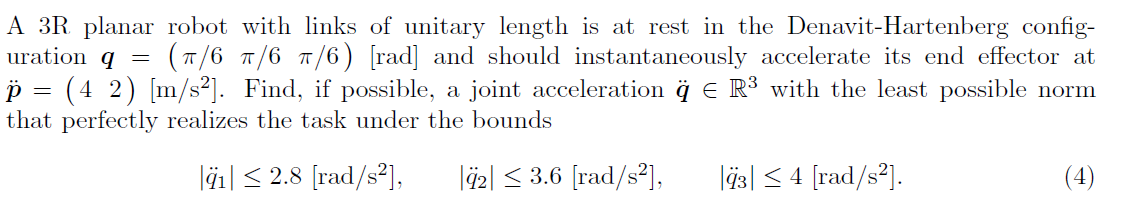

clear; clc;
V = [2.8,3.6,4] % Maximum acceleration constraints of joints

V =     2.8000    3.6000    4.0000


qnum = 3; %Number of joints
q = sym('q', [1 qnum]);
d = sym('d', [1 qnum]);
a = sym('a', [1 qnum]);

L = sym('l')

$$L = l$$


% a, alpha, 
R3Robot = [L 0 0 q(1);
           L 0 0 q(2);
           L 0 0 q(3)]

$$R3Robot = \left(\begin{array}{cccc} l & 0 & 0 & q_{1}\\ l & 0 & 0 & q_{2}\\ l & 0 & 0 & q_{3} \end{array}\right)$$

       
T0_EE = getTransformationMatrix(R3Robot)

$$T0\_EE = \left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}+q_{3}\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right) & 0 & l\,\left(\cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right)\\ \sin\left(q_{1}+q_{2}+q_{3}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right) & 0 & l\,\left(\sin\left(q_{1}+q_{2}+q_{3}\right)+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Calculate the Jacobian (Rotational)
config = 'RRR';
[Jp, Jo] = getJacobian(R3Robot,config)

$$Jp = \begin{array}{l} \left(\begin{array}{ccc} -l\,\left(\sigma_{1}+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right) & -l\,\left(\sigma_{1}+\sin\left(q_{1}+q_{2}\right)\right) & -l\,\sigma_{1}\\ l\,\left(\sigma_{2}+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right) & l\,\left(\sigma_{2}+\cos\left(q_{1}+q_{2}\right)\right) & l\,\sigma_{2}\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

$$Jo = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 1 & 1 \end{array}\right)$$

%Jac = [Jp;Jo]
%Eliminate the zero rows, which represent the unused variables
Jp = Jp(~all(Jp == 0,2),:)

$$Jp = \begin{array}{l} \left(\begin{array}{ccc} -l\,\left(\sigma_{1}+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right) & -l\,\left(\sigma_{1}+\sin\left(q_{1}+q_{2}\right)\right) & -l\,\sigma_{1}\\ l\,\left(\sigma_{2}+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right) & l\,\left(\sigma_{2}+\cos\left(q_{1}+q_{2}\right)\right) & l\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$


q1 = [pi/6, pi/6, pi/6]

q1 =     0.5236    0.5236    0.5236


J = subs(Jp, [q L], [q1 1])

$$J = \left(\begin{array}{ccc} -\frac{\sqrt{3}}{2}-\frac{3}{2} & -\frac{\sqrt{3}}{2}-1 & -1\\ \frac{\sqrt{3}}{2}+\frac{1}{2} & \frac{1}{2} & 0 \end{array}\right)$$

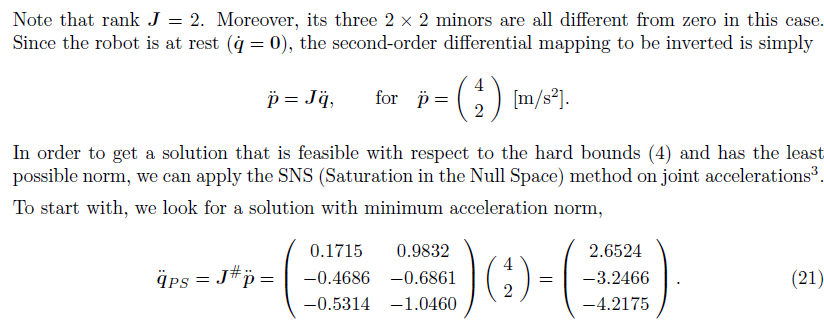

% SNS
xdot= [4,2].'

xdot =      4
     2


qdotPS = eval(pinv(J))*xdot

qdotPS =     2.6524
   -3.2466
   -4.2175


maxvalue = 1

maxvalue = 1

qdotstar = qdotPS

qdotstar =     2.6524
   -3.2466
   -4.2175


qdot_sns = qdotPS

qdot_sns =     2.6524
   -3.2466
   -4.2175


while maxvalue > 0
    [maxvalue, maxindex] = max(abs(qdotstar)-abs(V')) % The positive values are violating the limit. We take the highest one.
    if (maxvalue > 0) % if there is an exceeding value
        s = V(1)/qdotstar(maxindex)    
        %xdot_sns  = xdot - J(:,maxindex)* sign(qdotPS(maxindex))*V(maxindex)
        %Same as 
        xdot_sns  = xdot - abs(J(:,maxindex)*V(maxindex));
        Jtemp = J;
        Jtemp(:,maxindex) = [];
        qdot_components = eval(pinv(Jtemp)*xdot_sns).' 
        qdot_sns = [qdot_components(1:maxindex-1), V(maxindex), qdot_components(maxindex:end)]
        qdotstar = qdot_sns;
    else
        disp("[INFO] No values are exceeding the limits.")
        disp('Result:')
        qdotstar
    end
end

maxvalue = 0.2175

maxindex = 3

s = -0.6639

qdot_components =     2.7321   -3.4641


qdot_sns =     2.7321   -3.4641    4.0000


maxvalue =    -0.0679    0.6641    1.2000


maxindex =      1     1     1


[INFO] No values are exceeding the limits.


Result:


qdotstar =     2.7321   -3.4641    4.0000
